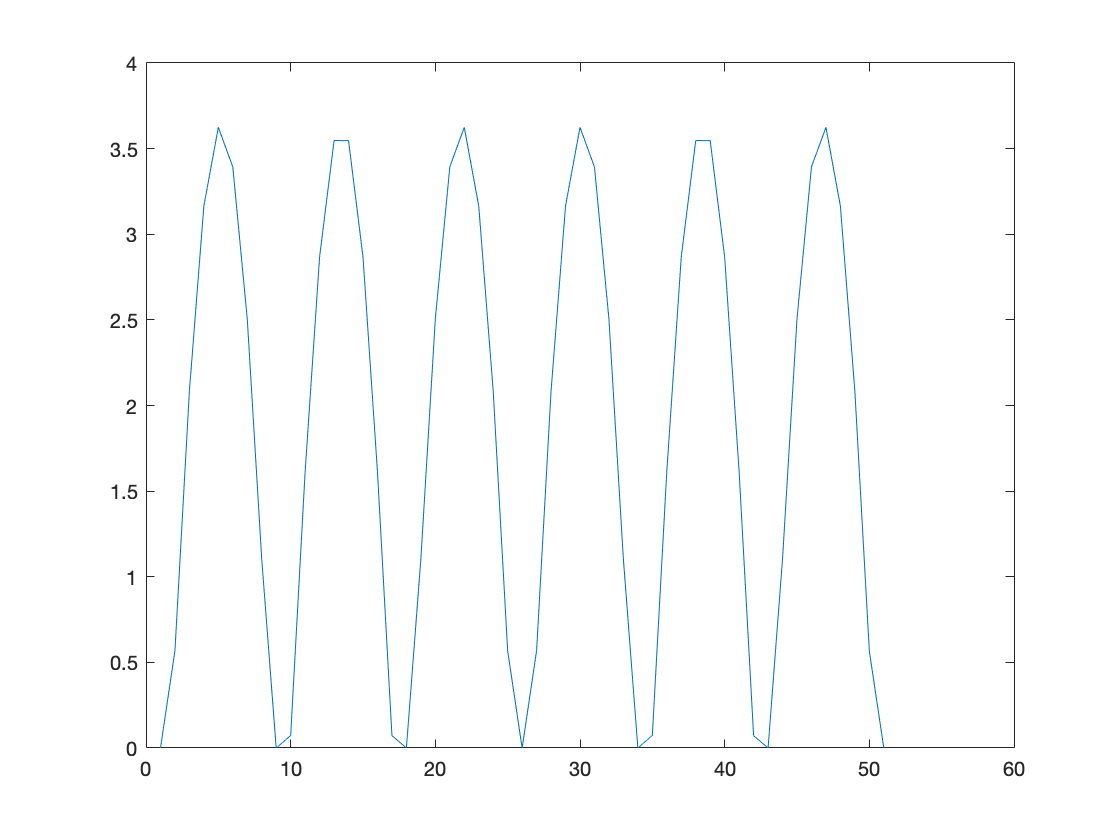

tic
Xguess=[0;0;0;0];
t=0;
iter=0;

for t=0:1e-3:0.05
    
 X=NewtonRaphson(Xguess,1e-4,t); 
[Fx,j]= nonlinearFunc(X,t);
    
iter=iter+1;


X2(iter) =X(2);
Xguess= X;

end 

plot(X2)

toc

Elapsed time is 0.490326 seconds.


function [X_final]  = NewtonRaphson(Xguess,tol,t)
x_prev=Xguess;

iteration=1;

for iteration=1:1000
    [F_prev,J_prev]  =  nonlinearFunc(x_prev,t);
    x_current = x_prev-(J_prev)^(-1)*F_prev;
   
    [F_current,J_current]  =  nonlinearFunc(x_current,t);
    Xout = F_current;
    
    normDeltaX(iteration)=norm(x_current - x_prev);
 
    if norm(Xout)<tol && (normDeltaX(iteration))<tol
        X_final=x_current;
       break 
    end
    
    x_prev=x_current;
   
     iteration=iteration+1;
    
end
end

function [F,J]  =  nonlinearFunc(X,t)
%outputs :
% F is the nonlinear function, 
% J is the Jacobian of the F.
%Input
% X is the vector of nodal voltages.
% input source 

U =  zeros(4,1);
U(4,1) = 5 * sin(377 * t);
U = U;

% G matrix 
G = zeros(4,4);

G(2,2) = 0.02;
G(4,1) = 1;
G(1,4) = 1;

G(4,3) = -1;
G(3,4) = -1;

% g vector

Is = 1e-13;
Vt = 0.025;
g(1,1) =  Is*( exp( (X(1) - X(2) )/Vt) -1)   - Is*( exp(- X(1)/Vt) -1)  ;

g(2,1) =-Is*( exp( (X(1) - X(2) )/Vt) -1)   - Is*( exp( (X(3)- X(2) )/Vt) -1)  ;

g(3,1) = Is*( exp( (X(3) - X(2) )/Vt) -1)   - Is*( exp( -X(3)/Vt) -1)  ;

g(4,1)=0;
%% Set of nonlinear equations 

F = G*X+g-U;

%% compute the Jacobian 



gdX(1,1) = (Is/Vt)*( exp( (X(1) - X(2) )/Vt) )   + (Is/Vt)*( exp(- X(1)/Vt) );

gdX(1,2) = -(Is/Vt)*( exp( (X(1) - X(2) )/Vt) ) ;


gdX(2,1) = -(Is/Vt)*( exp( (X(1) - X(2) )/Vt) ) ;

gdX(2,2) = (Is/Vt)*( exp( (X(1)- X(2) )/Vt) ) + (Is/Vt)*( exp( (X(3)- X(2) )/Vt) ) ;

gdX(2,3) = -(Is/Vt)*( exp( (X(3)- X(2) )/Vt)) ;


gdX(3,2) = -(Is/Vt)*( exp( (X(3)- X(2) )/Vt)) ;

gdX(3,3) = (Is/Vt)*( exp( (X(3)- X(2) )/Vt))  + (Is/Vt)*( exp( -X(3)/Vt) ); 

gdX(3,4) = 0;

gdX(4,:)=0;

J = G+gdX;


end 